% EE352 Automatic Control
% G4(s) = 100 / ((s+1)(s+2))

clc;
clear;
close all;

% G4(s) = 100 / ((s+1)*(s+2))
s = tf('s');
G4 = 100 / ((s + 1) * (s + 2));


[mag, phase, wout] = bode(G4);
mag_db = 20*log10(squeeze(mag));
phase_deg = squeeze(phase);

[min_diff, idx_wcp] = min(abs(mag_db));


Wcp_extracted = wout(idx_wcp);

Phase_at_Wcp = phase_deg(idx_wcp);

Pm_extracted = 180 + Phase_at_Wcp;

fprintf('\n--- Results Extracted from Bode Diagram Data ---\n');


--- Results Extracted from Bode Diagram Data ---


fprintf('Gain Crossover Frequency (Wcp) = %.2f rad/s\n', Wcp_extracted);

Gain Crossover Frequency (Wcp) = 9.80 rad/s


fprintf('Phase at Wcp                   = %.2f degrees\n', Phase_at_Wcp);

Phase at Wcp                   = -162.64 degrees


fprintf('Phase Margin (Pm)              = %.2f degrees\n', Pm_extracted);

Phase Margin (Pm)              = 17.36 degrees


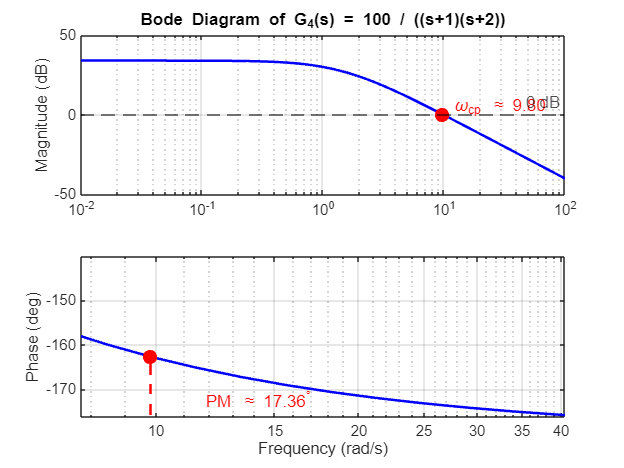


figure('Name', 'Bode Diagram with Extracted Margins');
subplot(2,1,1);
semilogx(wout, mag_db, 'b', 'LineWidth', 1.5);
hold on;
grid on;
title('Bode Diagram of G_4(s) = 100 / ((s+1)(s+2))');
ylabel('Magnitude (dB)');
yline(0, 'k--', '0 dB');
plot(Wcp_extracted, mag_db(idx_wcp), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
text(Wcp_extracted*1.2, 5, sprintf('\\omega_{cp} \\approx %.2f', Wcp_extracted), 'Color', 'r');

subplot(2,1,2);
semilogx(wout, phase_deg, 'b', 'LineWidth', 1.5);
hold on;
grid on;
ylabel('Phase (deg)');
xlabel('Frequency (rad/s)');
yline(-180, 'k--', '-180 deg');
plot(Wcp_extracted, Phase_at_Wcp, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot([Wcp_extracted Wcp_extracted], [-180 Phase_at_Wcp], 'r--', 'LineWidth', 1.5);
text(Wcp_extracted*1.2, Phase_at_Wcp - 10, sprintf('PM \\approx %.2f^\\circ', Pm_extracted), 'Color', 'r');